# Second-Order Lab: Second-Order Linear DEs in MATLAB

In this lab, you will learn how to use `iode` to plot solutions of second-order ODEs. You will also learn to classify the behaviour of different types of solutions.

Moreover, you will write your own Second-Order ODE system solver, and compare its results to those of `iode`.

Opening the m-file lab5.m in the MATLAB editor, step through each part using cell mode to see the results.

There are seven (7) exercises in this lab that are to be handed in on the due date of the lab.

## Student Information

## Iode for Second-Order Linear DEs with constant coefficients

In the `iode` menu, select the `Second order linear ODEs` module. It opens with a default DE and a default forcing function `f(t) = cos(2t)`. The forcing function can be plotted along with the solution by choosing `Show forcing function` from the `Options` menu.

Use this module to easily plot solutions to these kind of equations.

There are three methods to input the initial conditions:

Method 1. Enter the values for `t0`, `x(t0)`, and `x'(t0)` into the `Initial conditions` boxes, and then click `Plot solution`.

Method 2. Enter the desired slope `x'(t0)` into the appropriate into the `Initial conditions` box, and then click on the graph at the point `(t0,x(t0))` where you want the solution to start.

Method 3. Press down the left mouse button at the desired point `(t0,x(t0))` and drag the mouse a short distance at the desired slope `x'(t0)`. When you release the mouse button, `iode` will plot the solution.

## Growth and Decay Concepts

We want to classify different kinds of behaviour of the solutions. We say that a solution:

`grows` if its magnitude tends to `infinity` for large values of `t`, that is, if either the solution tends to $+\infty$ or $-\infty$,

`decays` if its magnitude converges to `0` for large values of `t`,

`decays while oscillating` if it keeps changing sign for large values of `t` and the amplitude of the oscillation tends to zero,

`grows while oscillating` if it keeps changing sign for large values of `t` and the amplitude of the oscillation tends to infinity.

## Example

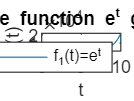

t = 0:0.1:10;

% Example 1
figure();
y1 = exp(t);
plot(t,y1)

% Annotate the figure
xlabel('t');
ylabel('f_1(t)');
title('The function e^t grows');
legend('f_1(t)=e^t');

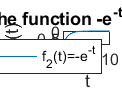




% Example 2
figure();
y2 = -exp(-t);
plot(t,y2)

% Annotate the figure
xlabel('t');
ylabel('f_2(t)');
title('The function -e^{-t} decays');
legend('f_2(t)=-e^{-t}');

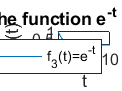




% Example 3
figure();
y3 = exp(-t);
plot(t,y3)

% Annotate the figure
xlabel('t');
ylabel('f_3(t)');
title('The function e^{-t} decays');
legend('f_3(t)=e^{-t}');

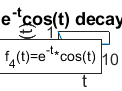




% Example 4
figure();
y4 = exp(-t).*cos(t);
plot(t,y4)

% Annotate the figure
xlabel('t');
ylabel('f_4(t)');
title('The function e^{-t}cos(t) decays while oscillating');
legend('f_4(t)=e^{-t}*cos(t)');

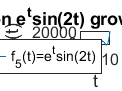




% Example 5
figure();
y5 = exp(t).*sin(2*t);
plot(t,y5)

% Annotate the figure
xlabel('t');
ylabel('f_5(t)');
title('The function e^{t}sin(2t) grows while oscillating');
legend('f_5(t)=e^{t}sin(2t)');

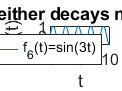




% Example 6
figure();
y6 = sin(3*t);
plot(t,y6)

% Annotate the figure
xlabel('t');
ylabel('f_6(t)');
title('The function sin(3t) neither decays nor grows, it just oscillates');
legend('f_6(t)=sin(3t)');




% |Remark.| A function which |grows while oscillating| doesn't |grow|,
% because it keeps changing sign, so it neither tends to $+\infty$ nor to
% $-\infty$.

## Exercise 1

Objective: Use `iode` to solve second-order linear DEs. And classify them.

Details: Consider the ODE:

(a) Use `iode` to plot six (6) numerical solutions of this equation with "random" initial data (use Method 3 above) and press-and-drag at various initial points, with some of the slopes being positive and some negative)

Use only initial points in the part of the window where `0<t<1` and `-1<x<1` and take all initial slopes between `-3` and `+3`.

Change the window to `[0,10]x[-3,3]`. Attach a cropped screenshot to your answers file.

(b) Based on the results of (a), state what percentage of solutions decay, grow, grow while oscillating, or decay while oscillating.

(c) Solve the DE and write the exact solution. Explain why this justifies your answer in (b).

% ======================================================================
% Exercise 1 Submission
% ======================================================================

% (a) In attached file titled "MAT292 Lab 5 - Exercises 1-3 [zhaoli50].pdf"

% (b) All solutions appear to decay (to x = 0) while oscillating.

% (c) Define real constants c1, c2 dependent on initial conditions
% General solution: x = c1*exp(-t/2)*cos(2t) + c2*exp(-t/2)*sin(2t)

% The general solution to the ODE consists of two trigonometric functions
% (which oscillate with t), each multiplied with a decaying exponential function.
% This justifies the end behaviour being decay with oscillation. 

% ======================================================================

## Exercise 2

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

% ======================================================================
% Exercise 2 Submission
% ======================================================================

% (a) In attached file titled "MAT292 Lab 5 - Exercises 1-3 [zhaoli50].pdf"

% (b) According to the plots generated by iode, all solutions appear to grow
% (to infinity or negative infinity). 
% However, upon examining the general solution (stated below in part c)), there is a set of solutions 
% that tends to 0 (the solutions where c1 = 0 to satisfy the initial conditions). As such, some
% solutions grow to infinity/negative infinity and some solutions decay to zero. 

% (c) General solution: x = c1*exp((t*(-sqrt(3) + 2))/2) + c2*exp((t*(-sqrt(3) - 2))/2)
% For large t, the second term in this solution disappears and the solution
% tends to infinity because of the first term. However, if c1 = 0 for some
% set of initial conditions, then the solution will decay to zero. As such,
% the behaviour described in b) is reasonable.

% ======================================================================

## Exercise 3

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

% ======================================================================
% Exercise 3 Submission
% ======================================================================

% (a) In attached file titled "MAT292 Lab 5 - Exercises 1-3 [zhaoli50].pdf"

% (b) According to the plots generated by iode, all solutions appear to decay to x = 0. 

% (c) General solution: x = c1*exp((t*(-sqrt(3) + sqrt(2)))/2) + c2*exp((t*(-sqrt(3) - sqrt(2)))/2)
% Since both eigenvalues are negative, both terms of the solution decay to
% zero as time goes to infinity. As such, exponential decay of all
% solutions is reasonable and expected. 

% ======================================================================

## Example

Consider the ODE:

The solution is

From this, it is easy to see that all solutions decay while oscillating.

Similarly, for the equation 

The solution is

which grows while oscillating.

## Exercise 4

Consider the fourth-order ODE:

(a) Find the general solution for this problem. You can use MATLAB to find the roots of the characteristic equation numerically with `roots`.

(b) Predict what percentage of solutions with random initial data will grow, decay, grow while oscillating, and decay while oscillating. Explain.

% ======================================================================
% Exercise 4 Submission
% ======================================================================

% (a)
char_eq = [1 2 6 2 5];
e_values = roots(char_eq)

e_values =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


% General solution: y = c1*exp(-t)*cos(2t) + c2*exp(-t)*sin(2t) + c3*cos(t) + c4*sin(t)


% (b)
% In general, the solutions of the above form will either:
% 1) Oscillate without growing or decaying (since the first two terms will decay to nearly 
% zero but the third and fourth terms will continue oscillating indefinitely as t -> infinity), or
% 2) Decay while oscillating (in the case that c3 = c4 = 0)

% Under the assumption of random initial data, it is relatively unlikely to
% have a case where c3 = c4 = 0. It is also difficult to predict the exact
% percentage of initial conditions that will result in the above
% conditions, so the percentages below can only be rough approximations.

% Grow: 0%
% Decay: 0%
% Grow while oscillating: 0%
% Decay while oscillating: <10%
% Oscillate: >90%
% ======================================================================

## Exercise 5

Objective: Classify equations given the roots of the characteristic equation.

Details: Your answer can consist of just a short sentence, as `grows` or  `decays while oscillating`.

Consider a second-order linear constant coefficient homogeneous DE with `r1` and `r2` as roots of the characteristic equation.

Summarize your conclusions about the behaviour of solutions for randomly chosen initial data when.

(a) `0 < r1 < r2`

(b) `r1 < 0 < r2`

(c) `r1 < r2 < 0`

(d) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha < 0`

(e) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha = 0`

(f) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha > 0`

% ======================================================================
% Exercise 5 Submission
% ======================================================================

% (a) grows
% (b) grows
% (c) decays
% (d) decays while oscillating
% (e) oscillates
% (f) grows whlie oscillating

% ======================================================================

## Numerical M

One way to create a numerical method for second-order ODEs is to approximate derivatives with finite differences in the same way of the Euler method.

This means that we approximate the first derivative by:

and

By writing these approximations into the ODE, we obtain a method to get `y[n+1]` from the previous two steps `y[n]` and `y[n-1]`.

The method for approximating solutions is:

1. Start with `y[0]=y0`

2. Then we need to get `y[1]`, but we can't use the method, because we don't have two iterations `y[0]` and `y[-1]`(!!). So we use Euler to get

y1 is the slope given by the initial condition

3. Use the method described above to get `y[n]` for `n=2,3,...`.

## Exercise 6

Objective: Write your own second-order ODE solver.

Details: Consider the second-order ODE

Write a second-order ODE solver using the method described above.

This m-file should be a function which accepts as variables (t0,tN,y0,y1,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0, y1 are the initial conditions of the ODE, and h is the stepsize. You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB lab 2). Name the function DE2_<UTORid>.m.

Note: you will need to use a loop to do this exercise. 

## Exercise 7

Objective: Compare your method with `iode`

Details: Use `iode` to plot the solution of the ODE  `y'' + exp(-t/5) y' + (1-exp(-t/5)) y = sin(2*t)` with the initial conditions  `y(0) = 1, y'(0) = 0`

Use the window to `[0,20]x[-2,2]` Without removing the figure window, plot your solution (in a different colour), which will be plotted in the same graph. 

Comment on any major differences, or the lack thereof.

clc
clear

% Set up and solve ODE using DE2_zhaoli50.m
% Define inline function y'' = f(t, y, y')
f = @(T, Y, Y_pr) sin(2*T) - exp(-T/5)*Y_pr + (1-exp(-T/5))*Y;

% Initial conditions
t0 = 0;
tN = 20;
y0 = 1;
y1 = 0;
h = 0.1;

% Get solution from ODE solver using step size h = 0.1
[T, Y] = DE2_zhaoli50(f, t0, tN, y0, y1, h);

T =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


Y_pr = 0

Y_dpr = 0.2185

Y_pr = 0.0218

Y_dpr = 0.4077

Y_pr = 0.0626

Y_dpr = 0.5644

Y_pr = 0.1191

Y_dpr = 0.6859

Y_pr = 0.1876

Y_dpr = 0.7706

Y_pr = 0.2647

Y_dpr = 0.8178

Y_pr = 0.3465

Y_dpr = 0.8280

Y_pr = 0.4293

Y_dpr = 0.8028

Y_pr = 0.5096

Y_dpr = 0.7449

Y_pr = 0.5841

Y_dpr = 0.6582

Y_pr = 0.6499

Y_dpr = 0.5471

Y_pr = 0.7046

Y_dpr = 0.4174

Y_pr = 0.7463

Y_dpr = 0.2749

Y_pr = 0.7738

Y_dpr = 0.1262

Y_pr = 0.7864

Y_dpr = -0.0220

Y_pr = 0.7842

Y_dpr = -0.1631

Y_pr = 0.7679

Y_dpr = -0.2909

Y_pr = 0.7388

Y_dpr = -0.3994

Y_pr = 0.6989

Y_dpr = -0.4836

Y_pr = 0.6505

Y_dpr = -0.5392

Y_pr = 0.5966

Y_dpr = -0.5632

Y_pr = 0.5403

Y_dpr = -0.5533

Y_pr = 0.4850

Y_dpr = -0.5090

Y_pr = 0.4341

Y_dpr = -0.4306

Y_pr = 0.3910

Y_dpr = -0.3197

Y_pr = 0.3590

Y_dpr = -0.1792

Y_pr = 0.3411

Y_dpr = -0.0130

Y_pr = 0.3398

Y_dpr = 0.1743

Y_pr = 0.3573

Y_dpr = 0.3771

Y_pr = 0.3950

Y_dpr = 0.5896

Y_pr = 0.4539

Y_dpr = 0.8057

Y_pr = 0.5345

Y_dpr = 1.0190

Y_pr = 0.6364

Y_dpr = 1.2239

Y_pr = 0.7588

Y_dpr = 1.4147

Y_pr = 0.9003

Y_dpr = 1.5868

Y_pr = 1.0589

Y_dpr = 1.7363

Y_pr = 1.2326

Y_dpr = 1.8605

Y_pr = 1.4186

Y_dpr = 1.9579

Y_pr = 1.6144

Y_dpr = 2.0281

Y_pr = 1.8172

Y_dpr = 2.0722

Y_pr = 2.0244

Y_dpr = 2.0924

Y_pr = 2.2337

Y_dpr = 2.0924

Y_pr = 2.4429

Y_dpr = 2.0768

Y_pr = 2.6506

Y_dpr = 2.0513

Y_pr = 2.8557

Y_dpr = 2.0223

Y_pr = 3.0580

Y_dpr = 1.9970

Y_pr = 3.2577

Y_dpr = 1.9828

Y_pr = 3.4559

Y_dpr = 1.9873

Y_pr = 3.6547

Y_dpr = 2.0178

Y_pr = 3.8565

Y_dpr = 2.0817

Y_pr = 4.0646

Y_dpr = 2.1854

Y_pr = 4.2832

Y_dpr = 2.3347

Y_pr = 4.5166

Y_dpr = 2.5346

Y_pr = 4.7701

Y_dpr = 2.7891

Y_pr = 5.0490

Y_dpr = 3.1010

Y_pr = 5.3591

Y_dpr = 3.4721

Y_pr = 5.7063

Y_dpr = 3.9031

Y_pr = 6.0966

Y_dpr = 4.3939

Y_pr = 6.5360

Y_dpr = 4.9432

Y_pr = 7.0303

Y_dpr = 5.5495

Y_pr = 7.5853

Y_dpr = 6.2105

Y_pr = 8.2063

Y_dpr = 6.9240

Y_pr = 8.8987

Y_dpr = 7.6876

Y_pr = 9.6675

Y_dpr = 8.4995

Y_pr = 10.5174

Y_dpr = 9.3584

Y_pr = 11.4533

Y_dpr = 10.2640

Y_pr = 12.4797

Y_dpr = 11.2172

Y_pr = 13.6014

Y_dpr = 12.2204

Y_pr = 14.8234

Y_dpr = 13.2776

Y_pr = 16.1512

Y_dpr = 14.3947

Y_pr = 17.5907

Y_dpr = 15.5796

Y_pr = 19.1486

Y_dpr = 16.8423

Y_pr = 20.8329

Y_dpr = 18.1951

Y_pr = 22.6524

Y_dpr = 19.6524

Y_pr = 24.6176

Y_dpr = 21.2307

Y_pr = 26.7407

Y_dpr = 22.9487

Y_pr = 29.0356

Y_dpr = 24.8273

Y_pr = 31.5183

Y_dpr = 26.8891

Y_pr = 34.2072

Y_dpr = 29.1589

Y_pr = 37.1231

Y_dpr = 31.6629

Y_pr = 40.2894

Y_dpr = 34.4294

Y_pr = 43.7323

Y_dpr = 37.4881

Y_pr = 47.4811

Y_dpr = 40.8705

Y_pr = 51.5682

Y_dpr = 44.6097

Y_pr = 56.0292

Y_dpr = 48.7405

Y_pr = 60.9032

Y_dpr = 53.2999

Y_pr = 66.2332

Y_dpr = 58.3270

Y_pr = 72.0659

Y_dpr = 63.8633

Y_pr = 78.4522

Y_dpr = 69.9534

Y_pr = 85.4476

Y_dpr = 76.6452

Y_pr = 93.1121

Y_dpr = 83.9906

Y_pr = 101.5112

Y_dpr = 92.0463

Y_pr = 110.7158

Y_dpr = 100.8743

Y_pr = 120.8032

Y_dpr = 110.5428

Y_pr = 131.8575

Y_dpr = 121.1275

Y_pr = 143.9702

Y_dpr = 132.7119

Y_pr = 157.2414

Y_dpr = 145.3891

Y_pr = 171.7803

Y_dpr = 159.2624

Y_pr = 187.7066

Y_dpr = 174.4467

Y_pr = 205.1513

Y_dpr = 191.0699

Y_pr = 224.2582

Y_dpr = 209.2742

Y_pr = 245.1857

Y_dpr = 229.2175

Y_pr = 268.1074

Y_dpr = 251.0748

Y_pr = 293.2149

Y_dpr = 275.0402

Y_pr = 320.7189

Y_dpr = 301.3283

Y_pr = 350.8517

Y_dpr = 330.1763

Y_pr = 383.8694

Y_dpr = 361.8458

Y_pr = 420.0540

Y_dpr = 396.6254

Y_pr = 459.7165

Y_dpr = 434.8326

Y_pr = 503.1998

Y_dpr = 476.8171

Y_pr = 550.8815

Y_dpr = 522.9632

Y_pr = 603.1778

Y_dpr = 573.6933

Y_pr = 660.5471

Y_dpr = 629.4717

Y_pr = 723.4943

Y_dpr = 690.8082

Y_pr = 792.5751

Y_dpr = 758.2633

Y_pr = 868.4014

Y_dpr = 832.4524

Y_pr = 951.6467

Y_dpr = 914.0520

Y_pr = 1.0431e+03

Y_dpr = 1.0038e+03

Y_pr = 1.1434e+03

Y_dpr = 1.1025e+03

Y_pr = 1.2537e+03

Y_dpr = 1.2111e+03

Y_pr = 1.3748e+03

Y_dpr = 1.3306e+03

Y_pr = 1.5079e+03

Y_dpr = 1.4620e+03

Y_pr = 1.6541e+03

Y_dpr = 1.6066e+03

Y_pr = 1.8147e+03

Y_dpr = 1.7656e+03

Y_pr = 1.9913e+03

Y_dpr = 1.9406e+03

Y_pr = 2.1853e+03

Y_dpr = 2.1331e+03

Y_pr = 2.3986e+03

Y_dpr = 2.3449e+03

Y_pr = 2.6331e+03

Y_dpr = 2.5779e+03

Y_pr = 2.8909e+03

Y_dpr = 2.8344e+03

Y_pr = 3.1743e+03

Y_dpr = 3.1166e+03

Y_pr = 3.4860e+03

Y_dpr = 3.4273e+03

Y_pr = 3.8287e+03

Y_dpr = 3.7692e+03

Y_pr = 4.2057e+03

Y_dpr = 4.1456e+03

Y_pr = 4.6202e+03

Y_dpr = 4.5599e+03

Y_pr = 5.0762e+03

Y_dpr = 5.0161e+03

Y_pr = 5.5778e+03

Y_dpr = 5.5184e+03

Y_pr = 6.1297e+03

Y_dpr = 6.0716e+03

Y_pr = 6.7368e+03

Y_dpr = 6.6807e+03

Y_pr = 7.4049e+03

Y_dpr = 7.3516e+03

Y_pr = 8.1400e+03

Y_dpr = 8.0905e+03

Y_pr = 8.9491e+03

Y_dpr = 8.9045e+03

Y_pr = 9.8396e+03

Y_dpr = 9.8012e+03

Y_pr = 1.0820e+04

Y_dpr = 1.0789e+04

Y_pr = 1.1899e+04

Y_dpr = 1.1877e+04

Y_pr = 1.3086e+04

Y_dpr = 1.3076e+04

Y_pr = 1.4394e+04

Y_dpr = 1.4398e+04

Y_pr = 1.5834e+04

Y_dpr = 1.5854e+04

Y_pr = 1.7419e+04

Y_dpr = 1.7458e+04

Y_pr = 1.9165e+04

Y_dpr = 1.9226e+04

Y_pr = 2.1087e+04

Y_dpr = 2.1175e+04

Y_pr = 2.3205e+04

Y_dpr = 2.3323e+04

Y_pr = 2.5537e+04

Y_dpr = 2.5690e+04

Y_pr = 2.8106e+04

Y_dpr = 2.8300e+04

Y_pr = 3.0936e+04

Y_dpr = 3.1176e+04

Y_pr = 3.4054e+04

Y_dpr = 3.4347e+04

Y_pr = 3.7489e+04

Y_dpr = 3.7843e+04

Y_pr = 4.1273e+04

Y_dpr = 4.1697e+04

Y_pr = 4.5442e+04

Y_dpr = 4.5946e+04

Y_pr = 5.0037e+04

Y_dpr = 5.0631e+04

Y_pr = 5.5100e+04

Y_dpr = 5.5796e+04

Y_pr = 6.0680e+04

Y_dpr = 6.1492e+04

Y_pr = 6.6829e+04

Y_dpr = 6.7774e+04

Y_pr = 7.3606e+04

Y_dpr = 7.4700e+04

Y_pr = 8.1076e+04

Y_dpr = 8.2339e+04

Y_pr = 8.9310e+04

Y_dpr = 9.0764e+04

Y_pr = 9.8387e+04

Y_dpr = 1.0005e+05

Y_pr = 1.0839e+05

Y_dpr = 1.1030e+05

Y_pr = 1.1942e+05

Y_dpr = 1.2161e+05

Y_pr = 1.3158e+05

Y_dpr = 1.3407e+05

Y_pr = 1.4499e+05

Y_dpr = 1.4783e+05

Y_pr = 1.5977e+05

Y_dpr = 1.6300e+05

Y_pr = 1.7607e+05

Y_dpr = 1.7973e+05

Y_pr = 1.9405e+05

Y_dpr = 1.9820e+05

Y_pr = 2.1387e+05

Y_dpr = 2.1857e+05

Y_pr = 2.3572e+05

Y_dpr = 2.4104e+05

Y_pr = 2.5983e+05

Y_dpr = 2.6583e+05

Y_pr = 2.8641e+05

Y_dpr = 2.9319e+05

Y_pr = 3.1573e+05

Y_dpr = 3.2337e+05

Y_pr = 3.4807e+05

Y_dpr = 3.5668e+05

Y_pr = 3.8373e+05

Y_dpr = 3.9343e+05

Y_pr = 4.2308e+05

Y_dpr = 4.3398e+05

Y_pr = 4.6647e+05

Y_dpr = 4.7873e+05

Y_pr = 5.1435e+05

Y_dpr = 5.2812e+05

Y_pr = 5.6716e+05

Y_dpr = 5.8261e+05

Y_pr = 6.2542e+05

Y_dpr = 6.4276e+05

Y_pr = 6.8970e+05

Y_dpr = 7.0914e+05

Y_pr = 7.6061e+05

Y_dpr = 7.8239e+05

Y_pr = 8.3885e+05

Y_dpr = 8.6325e+05

Y_pr = 9.2517e+05

Y_dpr = 9.5249e+05

Y_pr = 1.0204e+06

Y_dpr = 1.0510e+06

Y_pr = 1.1255e+06

Y_dpr = 1.1597e+06

Y_pr = 1.2415e+06

Y_dpr = 1.2797e+06

Y_pr = 1.3695e+06

Y_dpr = 1.4122e+06

Y_pr = 1.5107e+06

Y_dpr = 1.5584e+06

Y_pr = 1.6665e+06

Y_dpr = 1.7198e+06

Y_pr = 1.8385e+06

Y_dpr = 1.8980e+06

Y_pr = 2.0283e+06

Y_dpr = 2.0947e+06

Y_pr = 2.2378e+06

Y_dpr = 2.3118e+06

Y_pr = 2.4689e+06

Y_dpr = 2.5515e+06

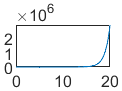


plot(T, Y);